# AE 6353 HW 1 - N Body Problem/Two-Body Problem

% Author: Albert Zheng
% Date: 8/28/24

% MATLAB code used for AE6353 HW1
% Local functions are appended to the end of this script

clear;clc;close all

## Question 1

Plots of the conic sections for parts a-e.

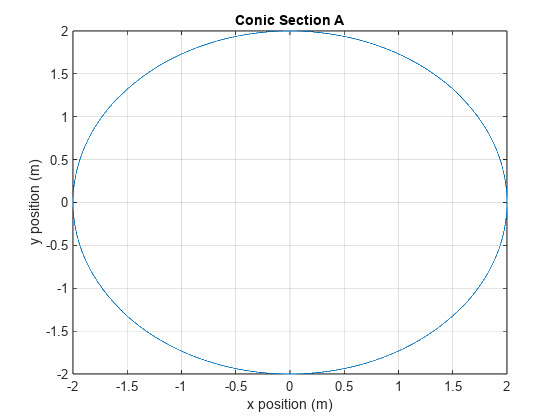

% Part A
[xA,yA] = getConicSection(2,0);

figure(1)
plot(xA,yA)
title('Conic Section A')
xlabel('x position (m)')
ylabel('y position (m)')
grid on

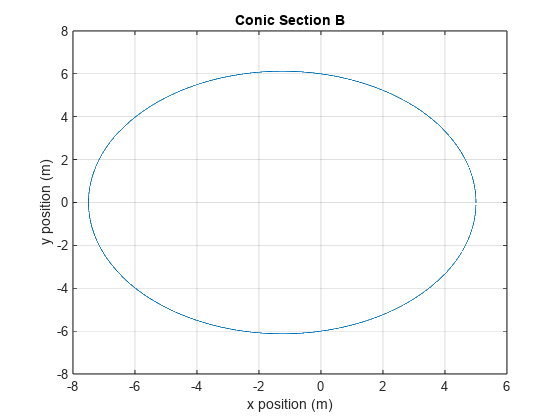


% Part B
[xB,yB] = getConicSection(6,0.2);
figure(2)
plot(xB,yB)
title('Conic Section B')
xlabel('x position (m)')
ylabel('y position (m)')
grid on

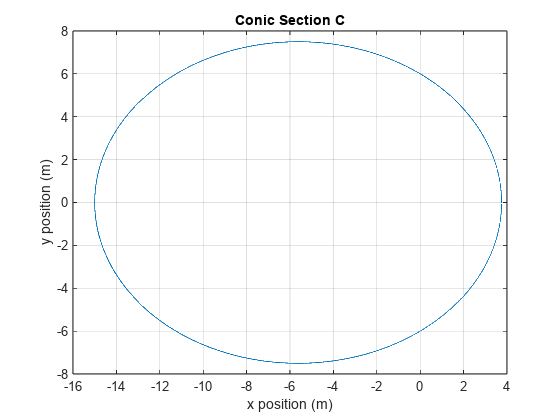


% Part C
[xC,yC] = getConicSection(6,0.6);

figure(3)
plot(xC,yC)
title('Conic Section C')
xlabel('x position (m)')
ylabel('y position (m)')
grid on

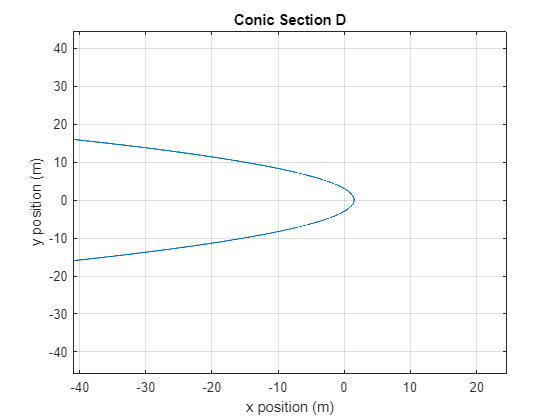


% Part D
[xD,yD] = getConicSection(3,1);

figure(4)
plot(xD,yD)
title('Conic Section D')
xlabel('x position (m)')
ylabel('y position (m)')
grid on
xlim([-41.0 24.6])
ylim([-45.8 44.5])

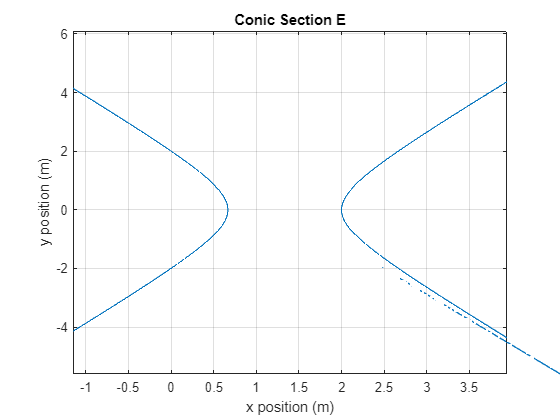


% Part E
[xE,yE] = getConicSection(2,2);

figure(5)
plot(xE,yE)
title('Conic Section E')
xlabel('x position (m)')
ylabel('y position (m)')
grid on

xlim([-1.15 3.94])
ylim([-5.6 6.1])

## Question 3

Numerically propagate an orbit around earth using the 2 body equation of motion. Adjusting the tolerance of the numerical integrator and analyzing its impacts.

Solved the two body problems with the following time steps (0.01, 0.1, 1, 10, 100, 1000 seconds).

Overall, the larger the step size, the greater the numerical instability during orbit propagation. This instability is visualized by observing that the orbits over time do not precisely overlap and seem "chunkier".

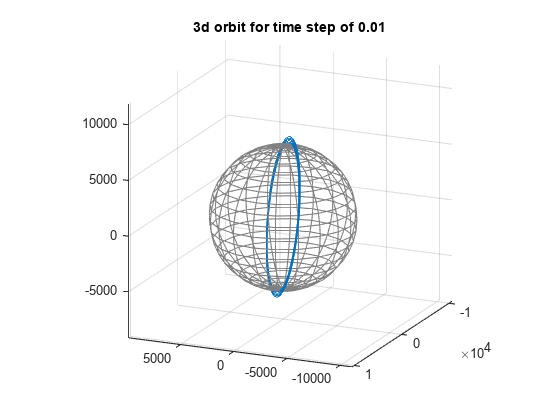

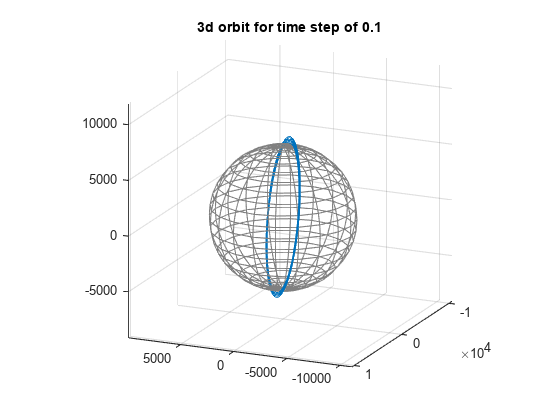

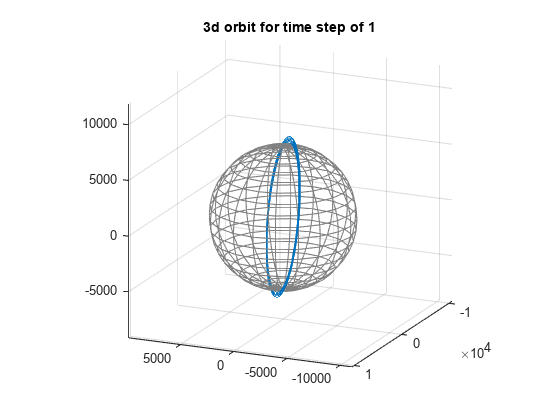

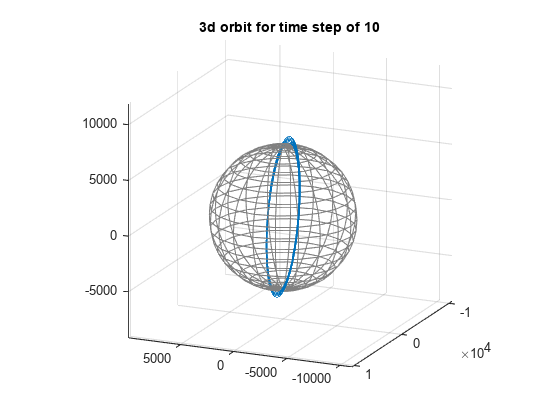

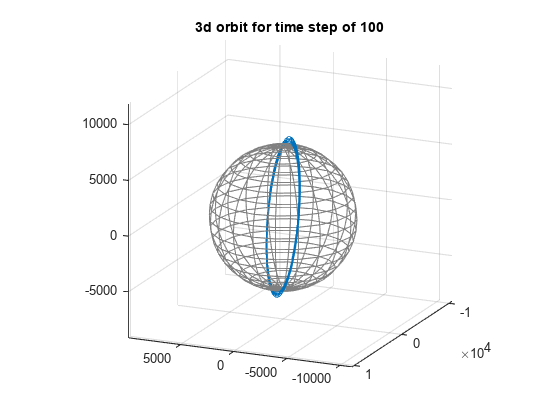

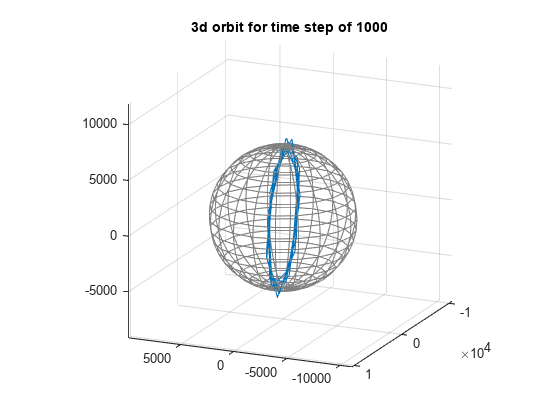

clear;clc;close all

mu = 3.986004418e5; % (km^3 * s^-2), for earth
initState = [3858.213;-5798.143;14.693;-0.863;-0.542;7.497]; % [km km km km/s km/s km/s]

% Test 5 different time steps (tolerances) to analyze the stability of the
% numerical integrator
timeSteps = [0.01 0.1 1 10 100 1000];
for timeStep = timeSteps

    tSpan = 0:timeStep:30000; % s
    [orbitT orbitX] = ode45(@(t,x) twoBodyModel(t,x,mu),tSpan,initState);
    
    figure(find(timeSteps==timeStep)+5) % "5" is from figures of previous code sections
    npanels = 20;
    erad = 6378.1; % equatorial radius (km)
    prad = 6356.8; % polar radius (km)
    axis(2e4*[-1 1 -1 1 -1 1]);
    view(9,26);
    hold on;
    axis vis3d;
    [xx yy zz] = ellipsoid(0,0,0,erad,erad,prad,npanels);
    globe = surf(xx,yy,-zz,'FaceColor','none','EdgeColor',0.5*[1 1 1]);
    
    plot3(orbitX(:,1),orbitX(:,2),orbitX(:,3))
    
    title('3d orbit for time step of ' + string(timeStep))
    axis equal
    grid on
    
    xlim([-11136 9893])
    ylim([-10580 10449])
    zlim([-9121 11909])

    view([204 17])

end

hold off

## Question 4

### Question 4a

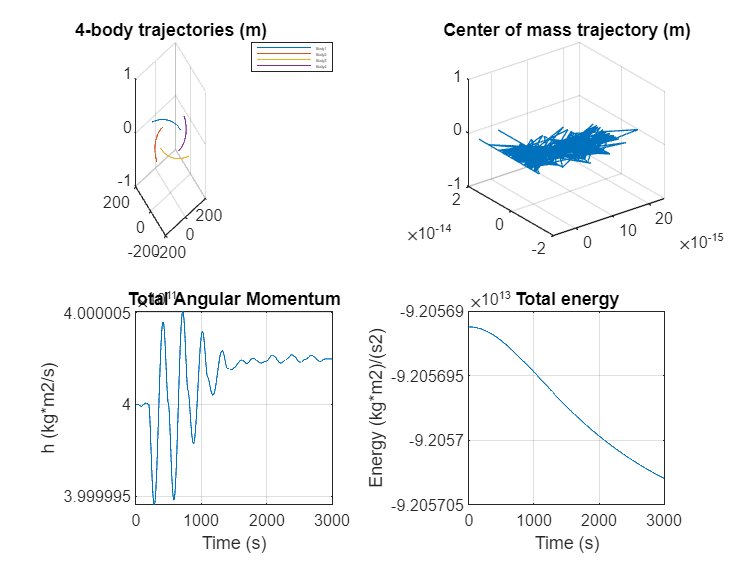

clear;clc;close all

nBodyConfig.timeStep = 1;
nBodyConfig.tSpan = 0:nBodyConfig.timeStep:3000; % s
nBodyConfig.masses = [1e10 1e10 1e10 1e10]; % (kg)
nBodyConfig.numBodies = 4;

initState1 = [100;0;0;0;0.1;0]; % [m m m m/s m/s m/s]
initState2 = [0;100;0;-0.1;0;0];
initState3 = [-100;0;0;0;-0.1;0];
initState4 = [0;-100;0;0.1;0;0];
nBodyConfig.initState = [initState1;initState2;initState3;initState4];
% nBodyConfig.initState = nBodyConfig.initState .* 1e-3; % convert to km and km/s

[orbitT orbitX] = ode45(@(t,x) nBodyModel(t,x,nBodyConfig),nBodyConfig.tSpan,nBodyConfig.initState);

% Get center of mass of the 4 body system
r_cm = centerOfMass(orbitX(:,[1 2 3 7 8 9 13 14 15 19 20 21]),nBodyConfig.masses,nBodyConfig.numBodies);

% Get total angular momentum
[h,hNorm] = totalAngularMomentum(orbitX,nBodyConfig.masses,nBodyConfig.numBodies);

% Get total energy
E = totalEnergy(orbitX,nBodyConfig.masses,nBodyConfig.numBodies);

figure(12)

subplot(2,2,1)
for i = 1:nBodyConfig.numBodies
    plot3(orbitX(:,6*(i-1)+1),orbitX(:,6*(i-1)+2),orbitX(:,6*(i-1)+3))
    hold on

end
title('4-body trajectories (m)')
grid on
hold off

lgd = legend('Body1','Body2','Body3','Body4');
set(lgd,'FontSize',2)

subplot(2,2,2)
plot3(r_cm(:,1),r_cm(:,2),r_cm(:,3))
title('Center of mass trajectory (m)')
grid on

subplot(2,2,3)
plot(orbitT,hNorm)
title('Total Angular Momentum')
xlabel('Time (s)')
ylabel('h (kg*m2/s)')
grid on

subplot(2,2,4)
plot(orbitT,E)
title('Total energy')
xlabel('Time (s)')
ylabel('Energy (kg*m2)/(s2)')
grid on

### Question 4b

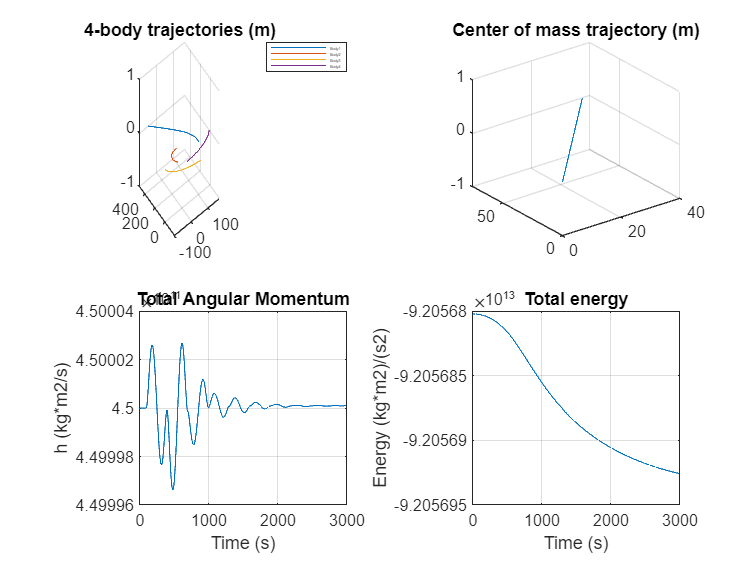

clear;clc;close all

nBodyConfig.timeStep = 1;
nBodyConfig.tSpan = 0:nBodyConfig.timeStep:3000; % s
nBodyConfig.masses = [1e10 1e10 1e10 1e10]; % (kg)
nBodyConfig.numBodies = 4;

initState1 = [100;0;0;0;0.2;0]; % [m m m m/s m/s m/s]
initState2 = [0;100;0;-0.05;0;0];
initState3 = [-100;0;0;0;-0.1;0];
initState4 = [0;-100;0;0.1;0;0];
nBodyConfig.initState = [initState1;initState2;initState3;initState4];
% nBodyConfig.initState = nBodyConfig.initState .* 1e-3; % convert to km and km/s

[orbitT orbitX] = ode45(@(t,x) nBodyModel(t,x,nBodyConfig),nBodyConfig.tSpan,nBodyConfig.initState);

% Get center of mass of the 4 body system
r_cm = centerOfMass(orbitX(:,[1 2 3 7 8 9 13 14 15 19 20 21]),nBodyConfig.masses,nBodyConfig.numBodies);

% Get total angular momentum
[~,hNorm] = totalAngularMomentum(orbitX,nBodyConfig.masses,nBodyConfig.numBodies);

% Get total energy
E = totalEnergy(orbitX,nBodyConfig.masses,nBodyConfig.numBodies);

figure(13)

subplot(2,2,1)
for i = 1:nBodyConfig.numBodies
    plot3(orbitX(:,6*(i-1)+1),orbitX(:,6*(i-1)+2),orbitX(:,6*(i-1)+3))
    hold on

end
title('4-body trajectories (m)')
grid on
hold off

lgd = legend('Body1','Body2','Body3','Body4');
set(lgd,'FontSize',2)

subplot(2,2,2)
plot3(r_cm(:,1),r_cm(:,2),r_cm(:,3))
title('Center of mass trajectory (m)')
grid on

subplot(2,2,3)
plot(orbitT,hNorm)
title('Total Angular Momentum')
xlabel('Time (s)')
ylabel('h (kg*m2/s)')
grid on

subplot(2,2,4)
plot(orbitT,E)
title('Total energy')
xlabel('Time (s)')
ylabel('Energy (kg*m2)/(s2)')
grid on

### Question 4c

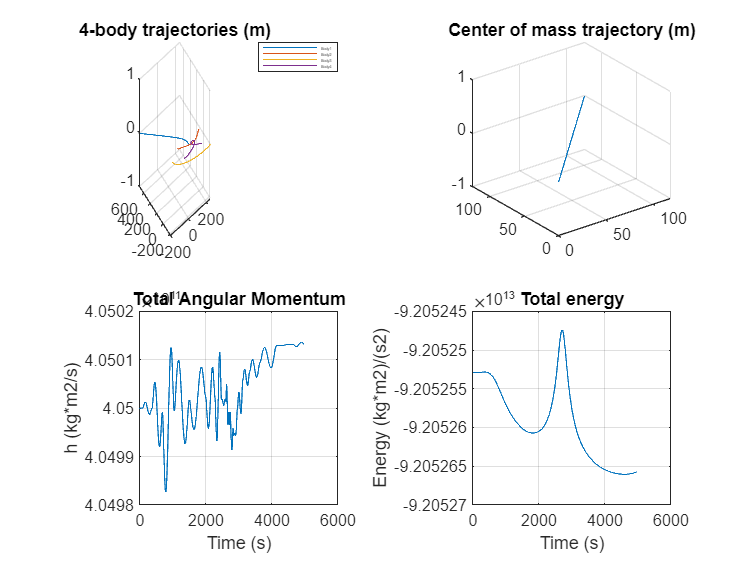

clear;clc;close all

nBodyConfig.timeStep = 0.01;
nBodyConfig.tSpan = 0:nBodyConfig.timeStep:5000; % s
nBodyConfig.masses = [1e10 1e10 1e10 1e10]; % (kg)
nBodyConfig.numBodies = 4;

initState1 = [100;0;0;0;0.2;0]; % [m m m m/s m/s m/s]
initState2 = [0;100;0;-0.005;0;0];
initState3 = [-100;0;0;0;-0.1;0];
initState4 = [0;-100;0;0.1;0;0];
nBodyConfig.initState = [initState1;initState2;initState3;initState4];
% nBodyConfig.initState = nBodyConfig.initState .* 1e-3; % convert to km and km/s

[orbitT orbitX] = ode45(@(t,x) nBodyModel(t,x,nBodyConfig),nBodyConfig.tSpan,nBodyConfig.initState);

% Get center of mass of the 4 body system
r_cm = centerOfMass(orbitX(:,[1 2 3 7 8 9 13 14 15 19 20 21]),nBodyConfig.masses,nBodyConfig.numBodies);

% Get total angular momentum
[h,hNorm] = totalAngularMomentum(orbitX,nBodyConfig.masses,nBodyConfig.numBodies);

% Get total energy
E = totalEnergy(orbitX,nBodyConfig.masses,nBodyConfig.numBodies);

figure(14)

subplot(2,2,1)
for i = 1:nBodyConfig.numBodies
    plot3(orbitX(:,6*(i-1)+1),orbitX(:,6*(i-1)+2),orbitX(:,6*(i-1)+3))
    hold on

end
title('4-body trajectories (m)')
grid on
hold off

lgd = legend('Body1','Body2','Body3','Body4');
set(lgd,'FontSize',2)

subplot(2,2,2)
plot3(r_cm(:,1),r_cm(:,2),r_cm(:,3))
title('Center of mass trajectory (m)')
grid on

subplot(2,2,3)
plot(orbitT,hNorm)
title('Total Angular Momentum')
xlabel('Time (s)')
ylabel('h (kg*m2/s)')
grid on

subplot(2,2,4)
plot(orbitT,E)
title('Total energy')
xlabel('Time (s)')
ylabel('Energy (kg*m2)/(s2)')
grid on

### Question 4d

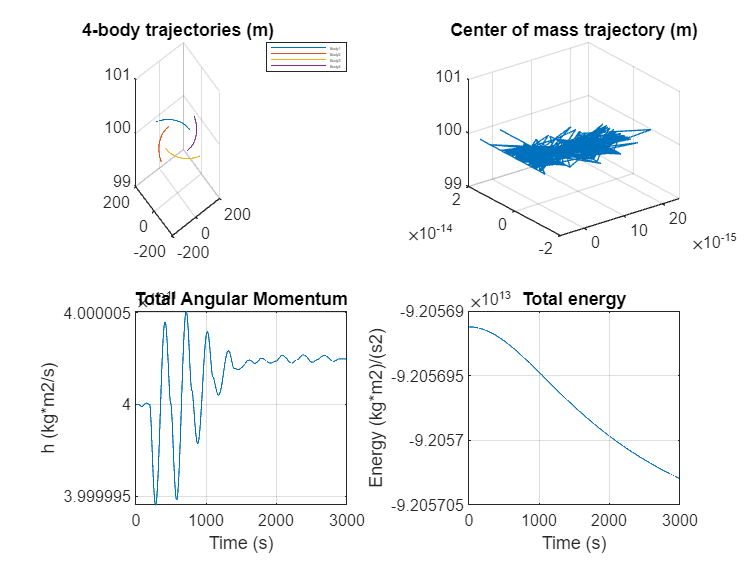

clear;clc;close all

nBodyConfig.timeStep = 1;
nBodyConfig.tSpan = 0:nBodyConfig.timeStep:3000; % s
nBodyConfig.masses = [1e10 1e10 1e10 1e10]; % (kg)
nBodyConfig.numBodies = 4;

initState1 = [100;0;100;0;0.1;0]; % [m m m m/s m/s m/s]
initState2 = [0;100;100;-0.1;0;0];
initState3 = [-100;0;100;0;-0.1;0];
initState4 = [0;-100;100;0.1;0;0];
nBodyConfig.initState = [initState1;initState2;initState3;initState4];
% nBodyConfig.initState = nBodyConfig.initState .* 1e-3; % convert to km and km/s

[orbitT orbitX] = ode45(@(t,x) nBodyModel(t,x,nBodyConfig),nBodyConfig.tSpan,nBodyConfig.initState);

% Get center of mass of the 4 body system
r_cm = centerOfMass(orbitX(:,[1 2 3 7 8 9 13 14 15 19 20 21]),nBodyConfig.masses,nBodyConfig.numBodies);

% Get total angular momentum
[h,hNorm] = totalAngularMomentum(orbitX,nBodyConfig.masses,nBodyConfig.numBodies);

% Get total energy
E = totalEnergy(orbitX,nBodyConfig.masses,nBodyConfig.numBodies);

figure(12)

subplot(2,2,1)
for i = 1:nBodyConfig.numBodies
    plot3(orbitX(:,6*(i-1)+1),orbitX(:,6*(i-1)+2),orbitX(:,6*(i-1)+3))
    hold on

end
title('4-body trajectories (m)')
grid on
hold off

lgd = legend('Body1','Body2','Body3','Body4');
set(lgd,'FontSize',2)

subplot(2,2,2)
plot3(r_cm(:,1),r_cm(:,2),r_cm(:,3))
title('Center of mass trajectory (m)')
grid on

subplot(2,2,3)
plot(orbitT,hNorm)
title('Total Angular Momentum')
xlabel('Time (s)')
ylabel('h (kg*m2/s)')
grid on

subplot(2,2,4)
plot(orbitT,E)
title('Total energy')
xlabel('Time (s)')
ylabel('Energy (kg*m2)/(s2)')
grid on

## Functions

### getConicSection

function [x, y] = getConicSection(p,e)
    %getConicSection Gets the conic section of an orbit using the orbit
    %equation in polar coordinates (r,f)
    % p - parameter/semi-lactus rectum
    % e - magnitude of eccentricity

    f = 0:0.001:2*pi-0.01; % span of true anomaly from 0 to 2pi
    r = p ./ (1 + e .* cos(f)); % span of ranges given the set of f's

    [x,y] = pol2cart(f,r); % convert from polar to cartesion


end

### twoBodyModel

function xDot = twoBodyModel(t,x,mu)
    % twoBodyModel Solve the 2 body problem
    % mu - must be in km

   rx = x(1); % km
   ry = x(2);
   rz = x(3);
   vx = x(4); % km/s
   vy = x(5);
   vz = x(6);

   r = [rx;ry;rz];
   v = [vx;vy;vz];
   accel = (-mu .* r) ./ (norm(r)^3);

   xDot = [v;accel];


end

### nBodyModel

% TODO reimplement using 0.5v^2 - mu/r
% h = r x v

function xDot = nBodyModel(t,x,config)
    % nBodyModel Solve the n body problem
    %
    % x = [r1;v1 ... rn;vn] (6nx1) (m and m/s)
    % config.masses - array of corresponding masses (nx1) (kg)
    %
    % xDot = [v1;a1 ... vn;an] (6nx1)

    n = config.numBodies;
    m = config.masses;
    Gmeters = 6.67430e-11; % (N*m^2)/(kg^2)
%     G = Gmeters * 1e-6;
    G = Gmeters;

    xDot = zeros(6*n,1);
    
    % calculate xdot for ith body
    for i = 1:n

        % get values
        r_i = x((6*(i-1))+(1:3)); % get position of ith body
        m_i = m(i); % get mass of ith body
        vel_i = x((6*(i-1))+(4:6));
        accel_i = [0;0;0]; % initialize acceleration of ith body

        % calculate effects of jth body on ith body
        jIndices = 1:n; % make j indices
        jIndices(i) = []; % delete to satisy j != i
        for j = jIndices

            % get values
            r_j = x((6*(j-1))+(1:3)); % get position of jth body
            m_j = m(j);
            r_ij = r_j - r_i;

            % add term
            accel_i = accel_i + ((m_i*m_j)/norm(r_ij)^3) * r_ij;

        end
        accel_i = accel_i * G/m_i;

        % insert xdots for body i
        xDot(6*(i-1)+(1:6)) = [vel_i;accel_i];

    end

end


### centerOfMass

function r_cm = centerOfMass(positions,masses,numBodies)
% centerOfMass Gets the center of mass trajectory of an n body system over
% time
% positions - [r1 r2 ... rn]
%   where each r is (numIterations,3) 
    
    positionsSize = size(positions);
    mwp = zeros(positionsSize(1),3); % mass weighted positions
    netMass = 0;

    for i = 1:numBodies
        m_i = masses(i);
        mwp = mwp + m_i .* positions(:,(3*(i-1)+(1:3)) );

        netMass = netMass + masses(i);
    end 

    r_cm = mwp ./ netMass;

end

### totalEnergy

function E = totalEnergy(states,masses,numBodies)
% totalEnergy Compute total energy of an n body system over time

    G = 6.67430e-11; % (N*m^2)/(kg^2)
    mu = 3.986004418e5; % (km^3 * s^-2), for earth
    E = 0;

    for i = 1:numBodies
        m_i = masses(i);

        v_i = states(:,6*(i-1)+(4:6)); % velocity traj of ith body
        v_i_norm = vecnorm(v_i,2,2); % velocity norm traj of ith body

        r_i = states((6*(i-1))+(1:3)); % position traj of ith body
        r_i_norm = vecnorm(r_i,2,2); % position norm traj of ith body


        E = E + m_i * ( 0.5 .* v_i_norm .^2 - (mu ./ r_i_norm) );

    end
    

end

### totalAngularMomentum

function [h,hNorm] = totalAngularMomentum(states,masses,numBodies)
% oldTotalAngularMomentum Compute total angular momentum of an n body system
% over time
%
% h = (mx3)

    statesSize = size(states);
    h = zeros(statesSize(1),3);
    hNorm = zeros(statesSize(1),1);

    for i = 1:numBodies
        m_i = masses(i);
        position_i = states(:,(6*(i-1)+(1:3)));
        velocity_i = states(:,(6*(i-1)+(4:6)));

        % note: cross(A,B,2) treats rows of A and B as vectors and returns
        % the cross products of corresponding rows
        h = h + cross(m_i.*position_i,velocity_i,2);

    end

    for i = 1:statesSize(1)
        hNorm(i) = norm(h(i,:));
    end


end

### oldTotalEnergy

function E = oldTotalEnergy(states,masses,numBodies)
% oldTotalEnergy Compute total energy of an n body system over time

    T = 0;
    V = 0;
    Gmeters = 6.67430e-11; % (N*m^2)/(kg^2)
%     G = Gmeters * 1e-6;
    G = Gmeters;

    % calculate kinetic energy
    for i = 1:numBodies
        % note: dot(A,B,2) treats the rows of A and B as vectors and
        % returns the dot products of corresponding rows
        
        m_i = masses(i);
        velocity_i = states(:,6*(i-1)+(4:6));
        T = T + dot(m_i .* velocity_i,velocity_i,2);

    end
    T = 0.5 * T;

    % calculate potential energy
    for i = 1:numBodies
        
        jIndices = 1:numBodies; % make j indices
        jIndices(i) = []; % delete to satisy j != i
        for j = jIndices
            
            m_i = masses(i);
            m_j = masses(j);
            r_i = states((6*(i-1))+(1:3)); % get position of ith body
            r_j = states((6*(j-1))+(1:3)); % get position of jth body
            r_ij = r_j - r_i;
            V = V + (m_i*m_j)/norm(r_ij);

        end

    end
    V = -0.5 * G * V;

    E = T + V;

end